# Task 4: Dynamic SSE of CPSs under adversarial attacks

We consider the problem of Task 3 with moving targets and sparse sensor attacks. There are 3 targets, moving according to the dynamics

 
$$x(k + 1) = Ax(k)$$


Basically, at each time step, the targets move towards left of one cell. The given $Y \in \mathbb{R}^{q,50}$ are the measurements for 50 time instants, i.e., for $k = 0, . . . , 49$. 

The scope of this task is to implement the sparse observer to track the moving targets and to identify which sensors are under attack.

### Useful notation

$z(k) = \left[\matrix{x(k) \cr a(k)}\right]$ ; $\hat z(k) = \left[\matrix{\hat x(k) \cr \hat a(k)}\right]$;$\hat z^+(k) = \left[\matrix{\hat x^+(k) \cr \hat a^+(k)}\right]$ $G = [D$ $I]$ 

Hint: $\Lambda = [10, . . . , 10, 20, . . . , 20]$ 

clear
close all
clc 

%% INITIALIZATION
load tracking_moving_targets.mat    %load A,D,Y

p=100;          %number of the cells
q=25;           %number of sensors

lambda1=10; lambda2=20; 
lambda=[lambda1*ones(p,1); lambda2*ones(q,1)];
eps=1e-8;                            
G = [D eye(q)];                     % augmented sensing matrix
G=normalize(G);                     
tau= (norm(G)^(-2))-eps;            % step size
mes_x = zeros(p,1);                 % save inside the matrix the estimate of x at each step
mes_a = zeros(q,1);                 % save inside the matrix the estimate of a at each step
z_hat = [zeros(p,1); zeros(q,1)];   % Initial state observer

x_true=zeros(p,1);
a_true=zeros(q,1);



## Options

In this program we have the possibility to set different parameters:

### number of target

The number of target to be tracked, in case of unawere attack the value must be set to 3

Ntarget=3;      %number of target to be tracked

### number of attack

The number of sensors under attack, it is used only for simulation purposes (in case of **aware attack**) not for data cleaning because in reality it is data that we are not aware of

Nattack=2;      %number of sensors under attack

### aware

The "aware" check box give us the possibility to simulate two different scenarios based on wheteher it is checked or not:

- **ckecked:** we generate de $Y \in \mathbb{R}^{q,T_{max}}$ output matrix in orderto simulate the case where the attacker know exactly the value of $y_i(k)$ and use it to inject a perturbance on the sensor's measurements equal to $a_i(k) =\frac{1}{2}y_i(k)
$ $\forall k=1,..,T_{max}$. The matrices  $A \in \mathbb{R}^{p,p}$ and $D \in \mathbb{R}^{q,p}$  are taken from the $tracking\_moving\_targets.mat$

- **not checked: **we take the matrices $A \in \mathbb{R}^{p,p}$ $D \in \mathbb{R}^{q,p}$ $Y \in \mathbb{R}^{q,T}$ by loading $tracking\_moving\_targets.mat$

% not checked:unaware attack;  checked:aware attack
aware = true;

### **change_sensors**

Give us the possibility to choose if the sensors under attack have to change every 25 seconds 

% not checked: the sensors under attack are always the same for 50 time istants
% checked: the sensors under attack change every 25 seconds
change_sensors=true; 

### Tmax

If the** aware option is checked** we can modify the $T_{max}$ value by putting a desired value **but** if also the **change_sensors option is checked** the desired value must be a multiple of 25

Tmax=50;

In order to avoid errors in the use of options, the following controls have been included 

if change_sensors==1 && aware==0
    return
end

if change_sensors && mod(Tmax,25)~=0
    return
elseif ~aware && Tmax~=50
    return
end
if ~aware && Ntarget~=3
    'The number of target must be 3'
    return
end
if ~aware && Nattack~=2
    'The number of sensors under attack must be 3'
    return
end

if aware    
    %generate inital condition on the position
    support_x_true = randperm(p);
    support_x_true = support_x_true(1:Ntarget); % I consider 3 targets
    x_true(support_x_true) = 1;


    %generate attack support
    tmp_supp_a = randperm(q);
    tmp_supp_a = tmp_supp_a(1:Nattack);
    
    sigma=1e-2; 
    noise = sigma*randn(q, 1);
    
    if change_sensors
        rep = Tmax/25;
        support_a_true=zeros(rep,Nattack);
        for i=1:rep        
            for j=((i-1)*25)+1:25*i %portion of Y to be filled
                x_true=A*x_true;
                Y(:,j) = D*x_true + a_true + noise;
                a_true(tmp_supp_a)=0.5*Y(tmp_supp_a,j);
            end
            %generate a new attack support
            a_true=zeros(q,1);
            support_a_true(i,:)=tmp_supp_a;
            tmp_supp_a = randperm(q);
            tmp_supp_a = tmp_supp_a(1:Nattack);
        end
    else
        for i=1:Tmax
            x_true=A*x_true;
            Y(:,i) = D*x_true + a_true + noise;
            a_true(tmp_supp_a)=0.5*Y(tmp_supp_a,i); 
        end
        support_a_true(1,:)=tmp_supp_a;
    end
else
    %The definition of initial condition on x_true and a_true are given 
    % only for graphical reason. In real cases we don't have the initial 
    % condition on the target and also we have to estimate which are the 
    % sensors under attack
    x_true = zeros(p,1);
    support_x_true = [87,23,36];
    x_true(support_x_true) = 1;
    
    a_true = zeros(q,1);
    support_a_true = [12,16];
    a_true(support_a_true) = 1;
    
end


### Sparse Observer

Now we apply the sparse observer: 


$$for$$
 
$$k=0:49$$
 
$$do$$


    
$$\hat z^+(k) = \mathbb{S}_{\tau \lambda} [\hat z(k) + \tau G^T (y(k) - G\hat z(k))]\\
\hat x(k + 1) = A\hat x^+(k)\\ 
\hat a(k + 1) = \hat a^+(k)$$



$$end$$

$$for$$


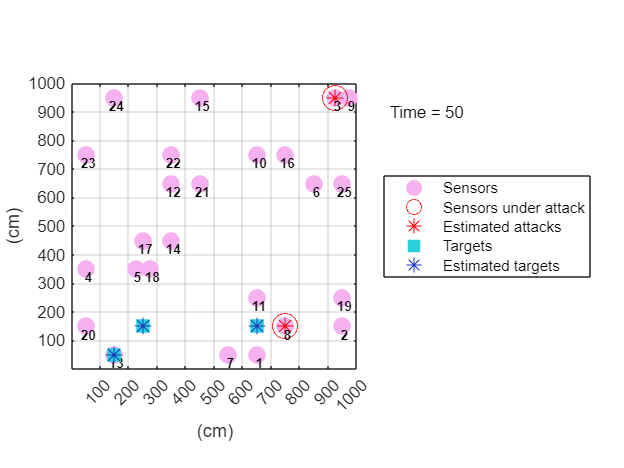

%------------------------SPARSE OBSERVER------------------------
z_hat_plus=zeros(p+q,1);
for k=1:Tmax
  
    arg=z_hat + tau*G'*(Y(:,k)-G*z_hat);                  %arg of STO
   
    for i=1:(p+q)
        z_hat_plus(i) = sto(arg(i), tau*lambda(i));        
    end
   
    z_hat=[A*z_hat_plus(1:p); z_hat_plus(p+1:end)];
    
    x_hat=A*z_hat_plus(1:p);
    a_hat=z_hat_plus(p+1:end);

    mes_x = [mes_x x_hat];
    mes_a = [mes_a a_hat];
end
mes_x = mes_x(:,2:end); % we delete the first colum that is all 0
mes_a = mes_a(:,2:end); % we delete the first colum that is all 0

%-------------------------Data cleaning--------------------------
for j=1:Tmax
    %cleaning x_hat
    max_x_vec = maxk(abs(mes_x(:,j)),Ntarget);
    for i=1:p 
        if(abs(mes_x(i,j))<max_x_vec(end))
            mes_x(i,j)=0; 
        end
    end

    %cleaning a_hat
    max_a = max(abs(mes_a(:,j)));
    for i=1:q
        if(abs(mes_a(i,j))<max_a*50/100)
            mes_a(i,j)=0; 
        end
    end
end
%Plot the room
[x_correct_estimate,a_correct_estimate, total_estimate] = room(mes_x,mes_a,1,Tmax,support_x_true,support_a_true,change_sensors);

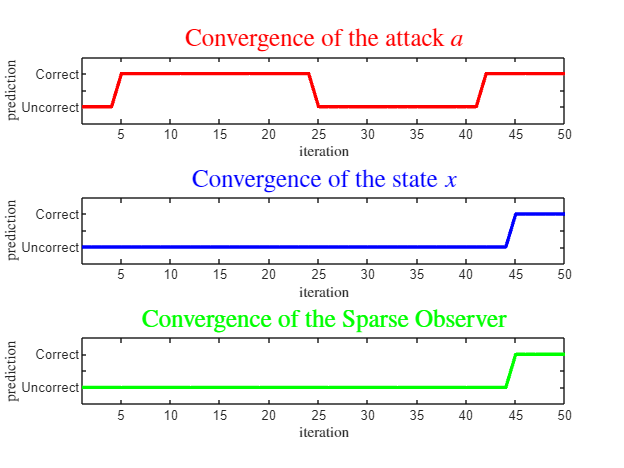

%%PLOT THE CONVERGENCE OF THE OBSERVER
time_interval = zeros(1,Tmax);
for k=1:1:Tmax
    time_interval(k) = k;
end
figure
grid on
subplot(3,1,1)
plot(time_interval,a_correct_estimate,'LineWidth',2,'Color','r');
ylim([-0.5,1.5]);
xlim([1,Tmax]);
title("Convergence of the attack $a$","Interpreter","latex","FontSize",15,"Color",'r');
xlabel("iteration","Interpreter","latex");
ylabel("prediction","Interpreter","latex");
yticklabels({'','Uncorrect', '','Correct'});
subplot(3,1,2)
grid on
plot(time_interval,x_correct_estimate,'LineWidth',2,'Color','b');
ylim([-0.5,1.5]);
xlim([1,Tmax]);
title("Convergence of the state $x$","Interpreter","latex","FontSize",15,"Color",'b');
xlabel("iteration","Interpreter","latex");
ylabel("prediction","Interpreter","latex");
yticklabels({'','Uncorrect', '','Correct'});
subplot(3,1,3)
grid on
plot(time_interval,total_estimate,'LineWidth',2,'Color','g');
ylim([-0.5,1.5]);
xlim([1,Tmax]);
title("Convergence of the Sparse Observer","Interpreter","latex","FontSize",15,"Color",'g');
xlabel("iteration","Interpreter","latex");
ylabel("prediction","Interpreter","latex");
yticklabels({'','Uncorrect', '','Correct'});